# EE 415 project 2: Fin Whale Detection

## Initializing Variables

clear all; clc
%audio load/read
filename =[];

[x,Fs] = audioread("audio1.wav");

L = 600;
step = L/4;
NFFT = 2^nextpow2(L);
time = length(x);

## DTFT of the sound signal

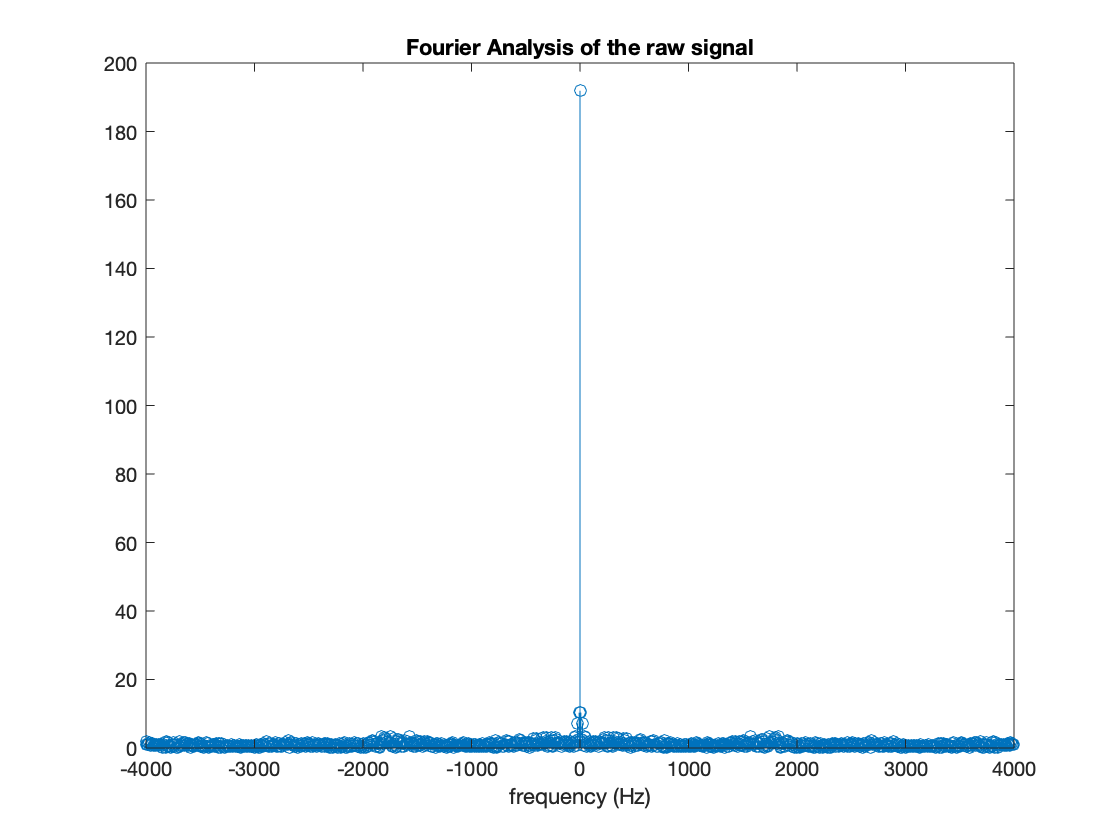

X = fft(x,NFFT);
f = Fs*(-NFFT/2:NFFT/2-1)/NFFT;
stem(f,fftshift(abs(X)))
xlabel('frequency (Hz)')
title('Fourier Analysis of the raw signal')

## DTFT of the down-sampled signal

n=5;
wc = 1/40;
[num,den] = butter(n,wc);
y = filter(num,den,x);
y= downsample(y,40);
Y = fft(y,NFFT);
stem(f,fftshift(abs(Y)))
xlabel('frequency (Hz)')
title('Fourier Analysis of the downsampled signal')

## Spectrogram of the downsampled signal

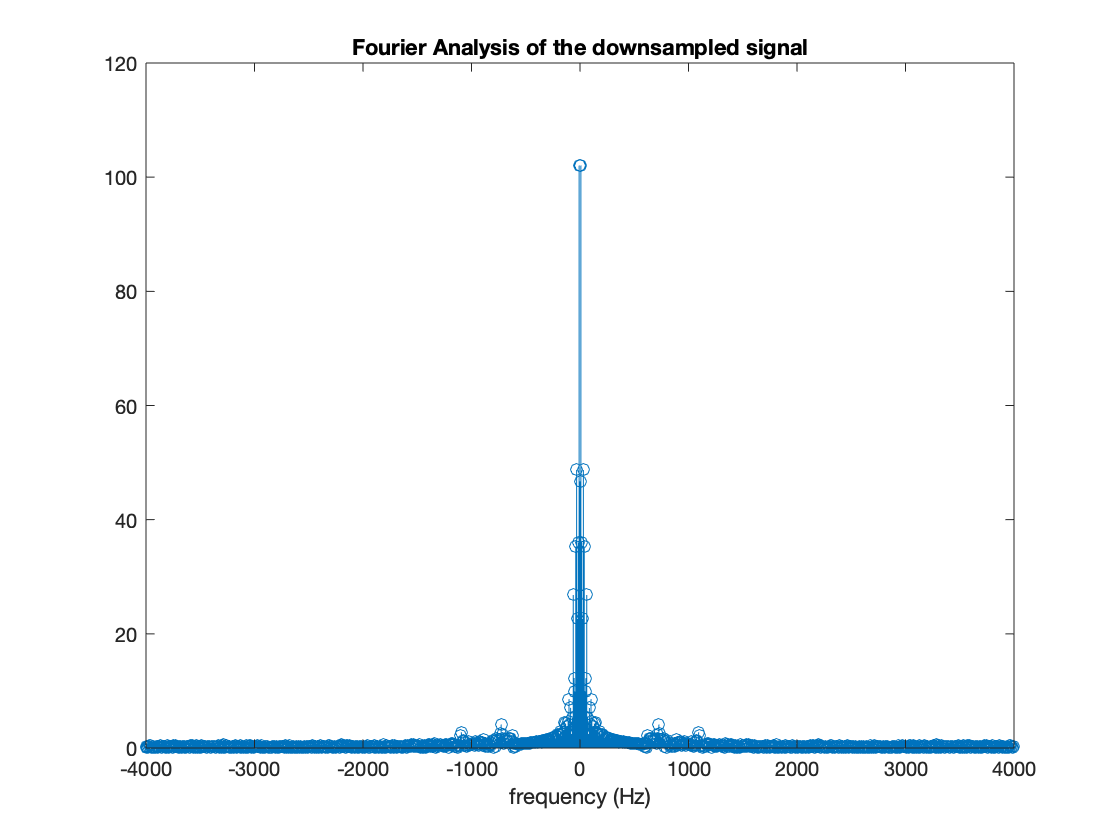

S=spectrogram0(y,L,NFFT,step,Fs);
plot_spectrogram(y,S,L,step,NFFT,Fs);

axis([0 7.4 500 1050])
xlabel('Time(s)')
ylabel('frequency (Hz)')
title('Spectrogram of the downsampled signal')

## Calculating average energy

for a=1:length(S(1,:))
    energy = mean(S(:,a));
    avg_f(a) = energy;
end

## Denoising S and Plotting it

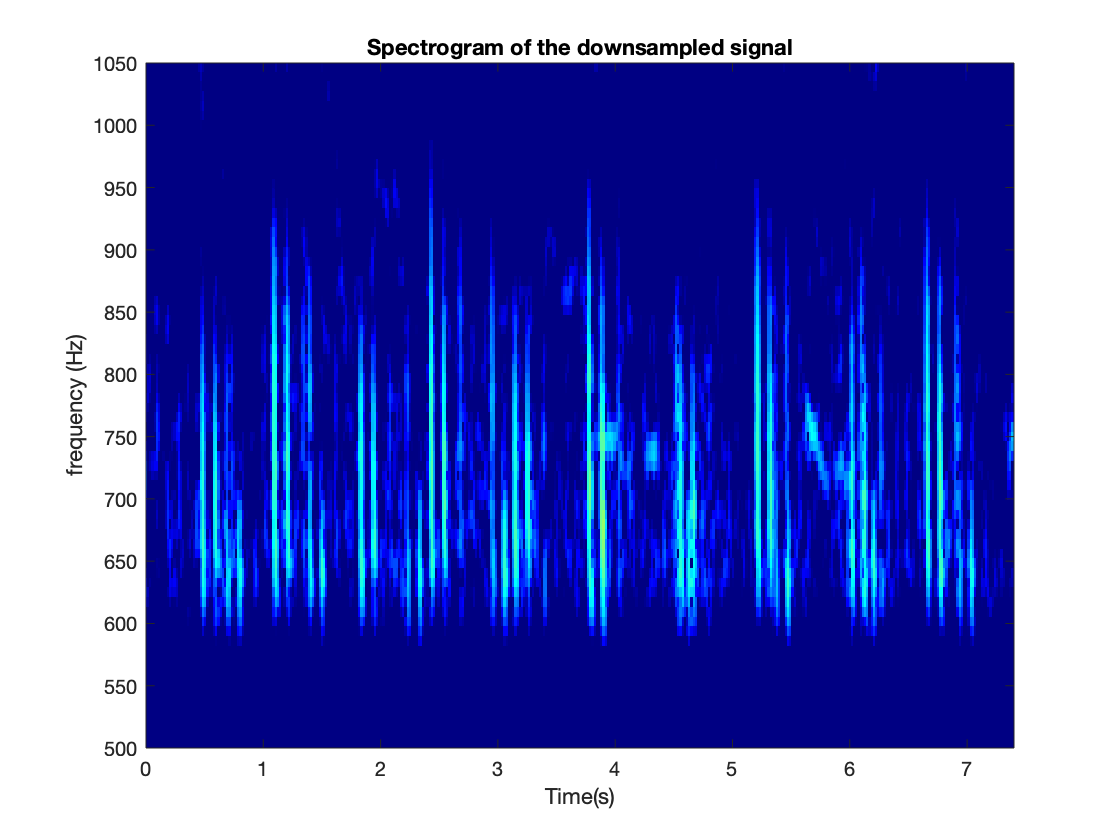

S_denoise = max(0,S-repmat(avg_f,size(S,1),1));
plot_spectrogram(y,S_denoise,L,step,NFFT,Fs);

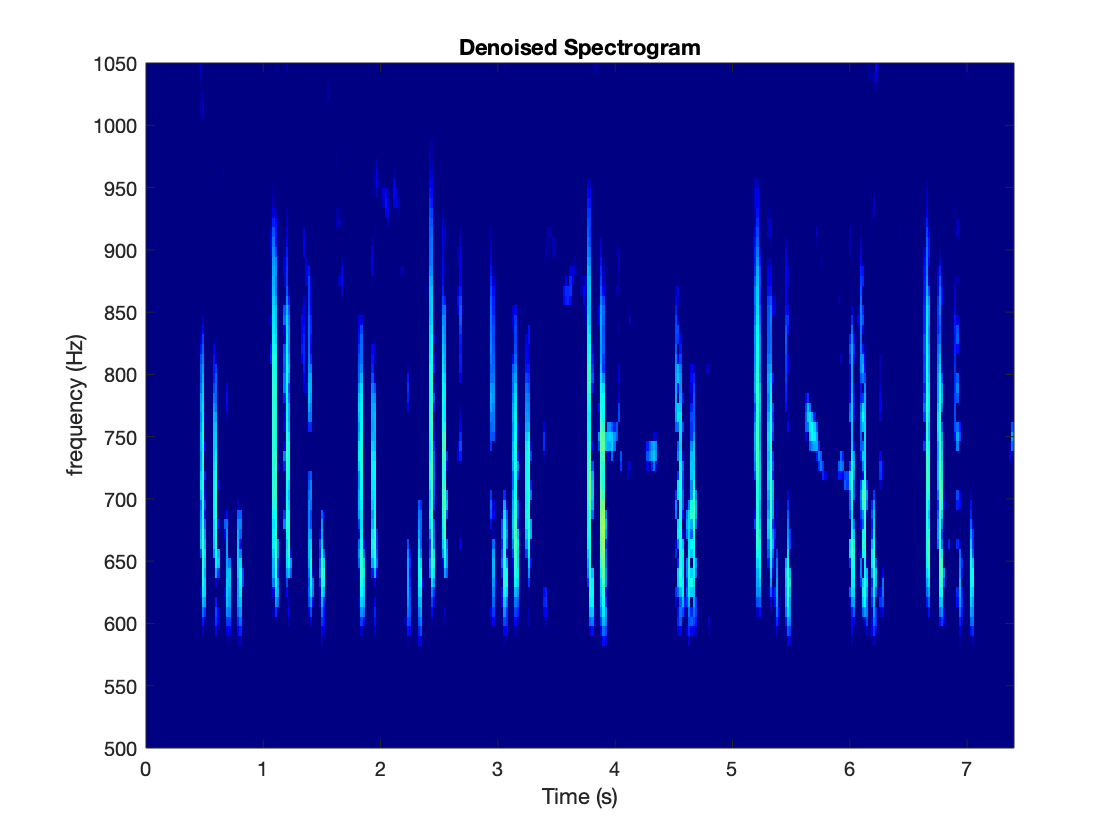

axis([0 7.4 500 1050])
title('Denoised Spectrogram')
xlabel('Time (s)')
ylabel('frequency (Hz)')

## Energy of the denoised S

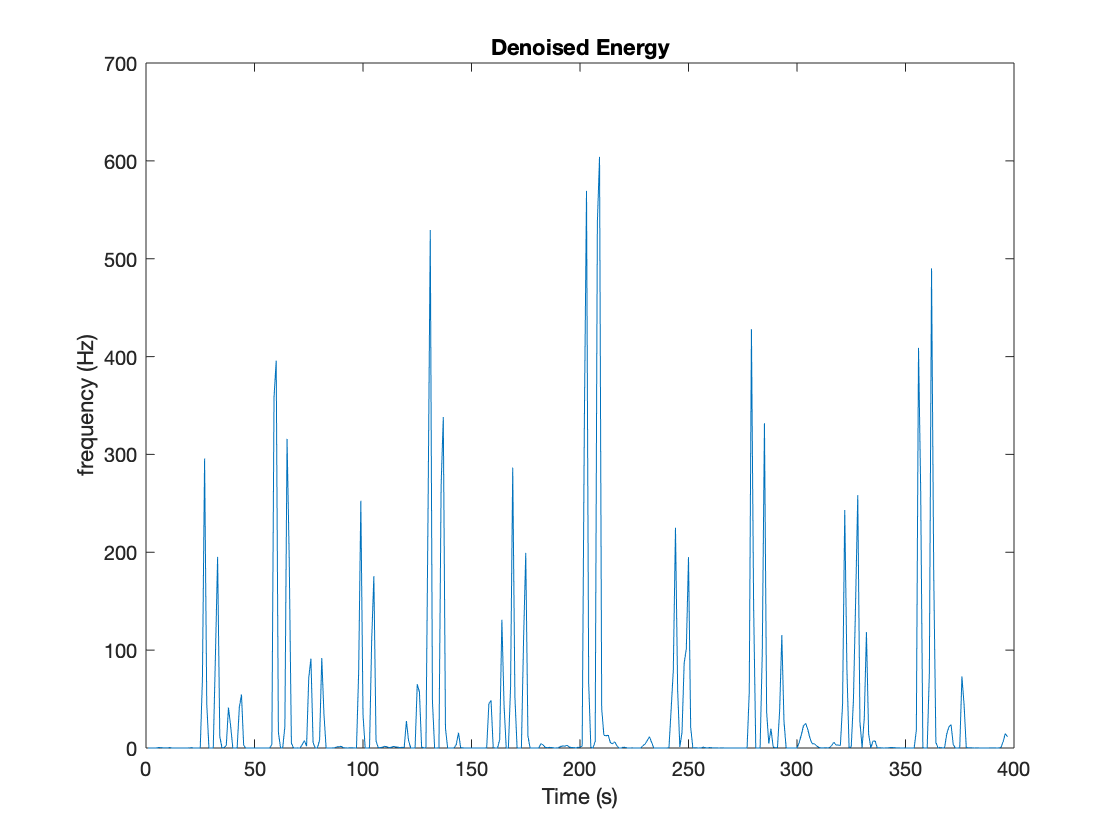

for b=1:length(S_denoise(:,1))
    energy = sum(S_denoise(b,70:128));
    E_denoise(b) = energy;
end
plot(E_denoise)
xlabel('Time (s)')
ylabel('frequency (Hz)')
title('Denoised Energy')

## Determining the peaks 

[pks,locs] = findpeaks(E_denoise,'Minpeakdistance',25,'Threshold',100)

pks =   295.7911  315.8353  252.7011  529.3383  286.4671  569.2786  225.0185  428.0174  258.3598  490.1714


locs =     27    65    99   131   169   203   244   279   328   362


finwhales = size(pks,2)

finwhales = 10

## Spectrogram functions

function S=spectrogram0(x,L,NFFT,step,Fs)
% S=spectrogram0(x,L,NFFT,step,Fs)
N=length(x); K=fix((N-L+step)/step);
w=hanning(L); time=(1:L)';
N2=NFFT/2+1; S=zeros(K,N2);
for k=1:K
    xw=x(time).*w;
    X=fft(xw,NFFT);
    X1=X(1:N2)';
    S(k,1:N2)=X1.*conj(X1);
    time=time+step;

end
end

function plot_spectrogram(x, S, L, step, NFFT,Fs)
    N=length(x);
    K=fix((N-L+step)/step);
    S=fliplr(S)'; S=S/max(max(S));
    %colormap(1-gray); 
    colormap(jet);
    tk=(0:K-1)'*step/Fs; 
    F=(0:NFFT/2)'*Fs/NFFT;
    imagesc(tk,flipud(F),20*log10(S),[-100 0]); 
    axis xy
end